# **UE1 USRP B210  Receiver **

## Set OFDM Frame Parameters

% Clear all the function data as they contain some persistent variables
clear;
clear helperOFDMRx helperOFDMRxFrontEnd helperOFDMRxSearch helperOFDMFrequencyOffset getTrParamsforSpecificBS_id;
close all;
% 第一部分可以认为是控制基站的功能
% The chosen set of OFDM parameters overall for all BSs:
overAllOfdmParams.online_BS               = 2;              % number of online data BS 
overAllOfdmParams.FFTLength               = 512;              % FFT length
overAllOfdmParams.CPLength                = ceil(overAllOfdmParams.FFTLength*0.25);   % Cyclic prefix length
overAllOfdmParams.Subcarrierspacing       = 30e3;               % Sub-carrier spacing of 30 KHz
total_RB                                  = 35;                                % User input Resource block number

% 调用calculateRBFinal函数确保最终的RB确定的子载波总数能够被pilot subcarrier spacing整除
[RB_verified, MaxRB] = calculateRBFinal(overAllOfdmParams, total_RB);
% 补充，其实新的算法不需要这个强限制，直接传入total RB即可

% check if RB_verified exceed MaxRB
if total_RB > MaxRB || RB_verified > MaxRB
    error('Error: Defined RB (%d) exceeds the system maximum allowed RB (%d). ', RB_verified, MaxRB);
end

overAllOfdmParams.total_RB                     = total_RB;
overAllOfdmParams.total_NumSubcarriers         = overAllOfdmParams.total_RB*12;                  % Number of sub-carriers in the band = resourceblock * 12 (must less than FFTlength)
overAllOfdmParams.guard_interval = (overAllOfdmParams.FFTLength - overAllOfdmParams.total_NumSubcarriers) / 2;     % Guard interval, 单侧的空载波
% check if NumSubcarriers less than FFTLength
if overAllOfdmParams.total_NumSubcarriers > overAllOfdmParams.FFTLength
    error('Total NumSubcarriers: (%d) exceeds Total FFTLength: (%d), which is not allowed. Please reduce the value of RB.', ...
        overAllOfdmParams.total_NumSubcarriers, overAllOfdmParams.FFTLength);
end


% 接下来是针对B210 UE联合分别接收不同基站数据的radio resource OFDM parametr 设置
overAllOfdmParams.Rcv_DL_CoopBSs_id                   = [1,2];                %当前服务该用户的下行基站协作集, 接收BS id信号处理的顺序与list前后顺序一致
overAllOfdmParams.PilotSubcarrierSpacing              = [36,36];              % Pilot sub-carrier spacing
overAllOfdmParams.BWPoffset                           = [0,0];                %当前基站的总带宽offset（单位/1个子载波），offset设置的是实际带宽start位置相对于初始计算的start的位置的偏移
UE_id                                                 = 1;                    %当前UE的ID标识符
% 遍历协作基站集，根据index计算当前BS id下要接收基站分配到的无线频谱资源, calculate allocated radio resource
for index = 1:length(overAllOfdmParams.Rcv_DL_CoopBSs_id)
    [OFDMParams, dataParams, all_radioResource] = getTrParamsforSpecificBS_id(overAllOfdmParams, index);
end

## Initialize Receiver Parameters

radioDevice            = "B210";   % Choose radio device for reception
channelmapping         = 1;  % mutichannel or single channel selection
centerFrequency        = 2.5e9;  % Center Frequency
centerFrequency        = 2.7e9;
gain                   = 60;  % Set radio gain
gain                   = 55;
save_data              = false;
read_savedData         = false;

read_filename = 'saved_frameData_qam64_cooperateTRdebug.bb';            % read saved received data from specific filename         
save_filename = 'saved_frameData_qam64_cooperateTRdebug.bb';           % save receiving data to specific filename

[sysParam,txParam,transportBlk_bs1,transportBlk_bs2] = helperOFDMSetParamsSDR(OFDMParams,dataParams,all_radioResource);
sysParam.total_usedSubcc = overAllOfdmParams.total_NumSubcarriers;
sysParam.total_usedRB = overAllOfdmParams.total_RB;
sampleRate                       = sysParam.scs*sysParam.FFTLen;                % Sample rate of signal
sysParam.enableTimescope = false;
sysParam.enableCFO = true;
sysParam.enableCPE = true;
sysParam.enableChest = true;
sysParam.enableHeaderCRCcheck = true;

if read_savedData
    bbr = comm.BasebandFileReader(read_filename, ...
    SamplesPerFrame=sysParam.txWaveformSize);
end
ofdmRx = helperGetRadioParams(sysParam,radioDevice,sampleRate,centerFrequency,gain,channelmapping);
[radio,spectrumAnalyze,constDiag, timesink, constellation_measure] = helperGetRadioRxObj(ofdmRx);
% timesink = 1;
constDiag.ShowTrajectory = false;

## Execute Receiver Loop

#### Synchronization

#### Frequency Offset Estimation and Correction

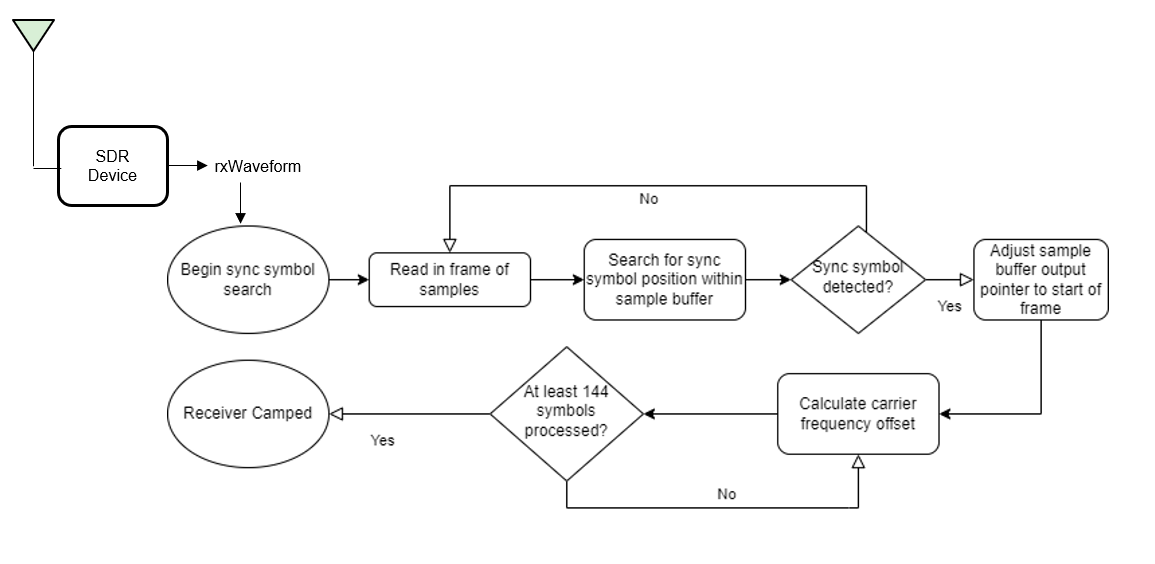

### Receiver Processing

#### Channel Estimation and Equalization

#### Header Decoding

#### Data Decoding

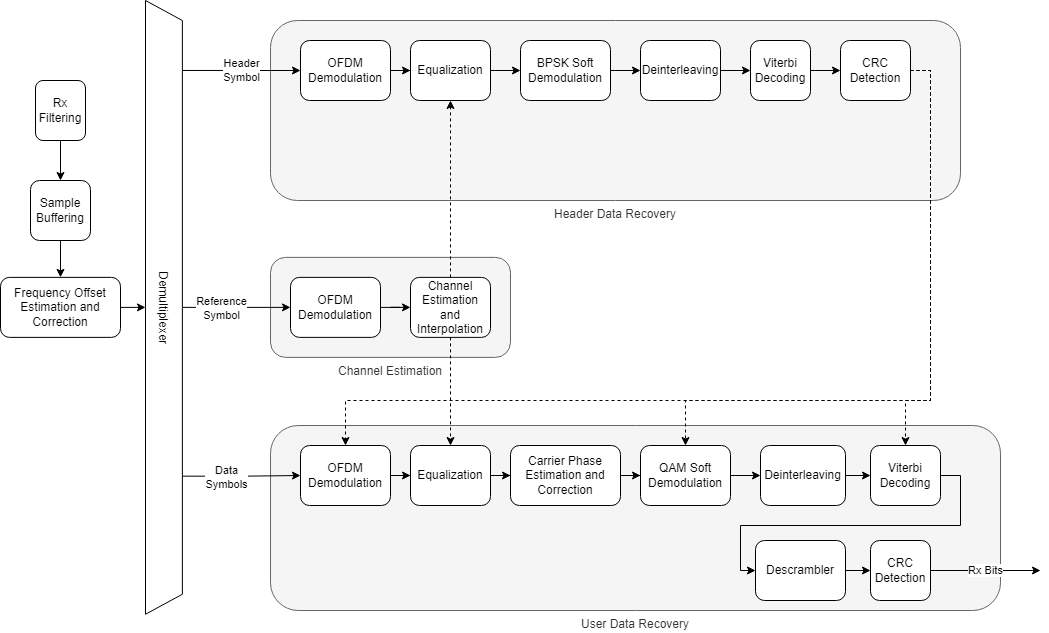


errorRate_bs1 = comm.ErrorRate();
errorRate_bs2 = comm.ErrorRate();
toverflow = 0; % Receiver overflow count
rxObj = helperOFDMRxInit(sysParam);
BER_bs1 = zeros(1,dataParams.numFrames);
BER_bs2 = zeros(1,dataParams.numFrames);
data_collec = [];
for frameNum = 1:dataParams.numFrames
    sysParam.frameNum = frameNum;
    if read_savedData
        rxWaveform = bbr();
        overflow = 0;
    else
        [rxWaveform, ~, overflow] = radio();
    end
    
    if save_data
        data_collec = [data_collec;rxWaveform];
    end
    toverflow = toverflow + overflow;

    % Run the receiver front-end only when there is no overflow
    if ~overflow
        rxIn = helperOFDMRxFrontEnd(rxWaveform,sysParam,rxObj);

        % Run the receiver processing
        [rxDataBits,isConnected,toff,rxDiagnostics] = helperOFDMRx(rxIn,sysParam,rxObj, timesink);
        sysParam.timingAdvance = toff;

        % Collect bit and frame error statistics
        if isConnected
            % Continuously update the bit error rate using the |comm.ErrorRate|
            % System object
            berVals_bs1 = errorRate_bs1(...
                transportBlk_bs1((1:sysParam.trBlkSize)).', ...
                rxDataBits);
            BER_bs1(frameNum) = berVals_bs1(1);

            berVals_bs2 = errorRate_bs2(...
                transportBlk_bs2((1:sysParam.trBlkSize)).', ...
                rxDataBits);
            BER_bs2(frameNum) = berVals_bs2(1);
            if dataParams.printData
                % As each character in the data is encoded by 7 bits, decode the received data upto last multiples of 7
                numBitsToDecode = length(rxDataBits) - mod(length(rxDataBits),7);
                recData = char(bit2int(reshape(rxDataBits(1:numBitsToDecode),7,[]),7));
                fprintf('Received data in frame %d: %s',frameNum,recData);
            end
        end

        if isConnected && dataParams.enableScopes
            constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), ...
                complex(rxDiagnostics.rxConstellationData(:)));
        end

        rmsEVM_header = 0; 
        rmsEVM_data = 0; 
        merdb_header = 0;
        merdb_data = 0;

        if isConnected && dataParams.enableConst_measure
            rmsEVM_header = constellation_measure.evm_header(complex(rxDiagnostics.rxConstellationHeader(:))); 
            rmsEVM_data = constellation_measure.evm_data(complex(rxDiagnostics.rxConstellationData(:))); 
            merdb_header = constellation_measure.mer_header(complex(rxDiagnostics.rxConstellationHeader(:)));
            merdb_data = constellation_measure.mer_data(complex(rxDiagnostics.rxConstellationData(:)));
        end

        if dataParams.enableScopes
            spectrumAnalyze(rxWaveform);
        end
    end
end
% Display the mean BER value across all frames
fprintf(['Simulation complete!\n' ...
    'BS1 massage Average BER = %d \n' ...
    'BS2 massage Average BER = %d \n' ...
    '-------measurement-------\n' ...
    'Header rms EVM(%%): %.3f %% \n' ...
    'Data rms EVM(%%): %.3f %% \n' ...
    'Header MER(dB): %.3f dB \n' ...
    'Data MER(dB): %.3f dB'],mean(BER_bs1),mean(BER_bs2),rmsEVM_header, rmsEVM_data, merdb_header, merdb_data)
% fprintf('-------measurement-------')
% fprintf('Header rms EVM(%%): %.3f %%', rmsEVM_header)
% fprintf('Data rms EVM(%%): %.3f %%', rmsEVM_data)
% fprintf('Header MER(dB): %.3f dB', merdb_header)
% fprintf('Data MER(dB): %.3f dB', merdb_data)
if save_data
    bbw = comm.BasebandFileWriter(save_filename,SampleRate=sampleRate,CenterFrequency=centerFrequency);
    bbw(data_collec);
    info(bbw)
    release(bbw)
end
if read_savedData
    release(bbr)
end
release(radio);